# Análisis de los experimentos con especies virtuales

PointsAll = [];
CoeffsAll = [];
DistanceMetricAll = [];
AreaMetricAll = [];
RocAll = [];

for i = 1 : 4
%     load("OLDMODEL/Test/2_5KM/Test" + num2str(i) + "_SA_25_NoAlpha.mat")
    load("Test_clustering_alpha_" + num2str(i) + ".mat")
    PointsAll = [PointsAll; Points];  
    CoeffsAll = [CoeffsAll; Coeffs];
    DistanceMetricAll = [DistanceMetricAll, DistanceMetric];
    AreaMetricAll = [AreaMetricAll, AreaMetric];
    RocAll = [RocAll, Roc];
end

Points = PointsAll;
Coeffs = CoeffsAll;
DistanceMetric = DistanceMetricAll;
AreaMetric = AreaMetricAll;
Roc = RocAll;

clear PointsAll CoeffsAll DistanceMetricAll AreaMetricAll RocAll

1. Criterio gráfico

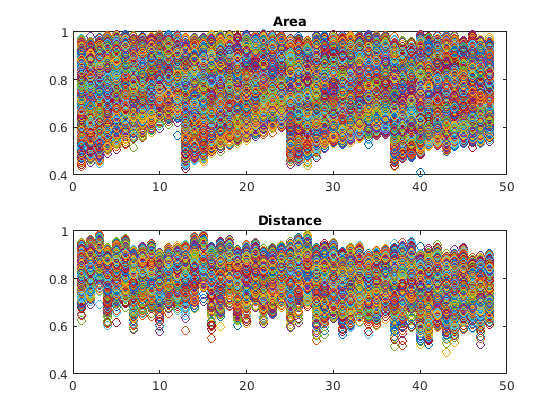

close all
subplot(2,1,1)
plot(AreaMetric, 'o')
title('Area')
subplot(2,1,2)
plot(DistanceMetric, 'o')
title('Distance')

% plot3(OccupExp,SampExp,DistanceMetric, 'o')
% xlabel('OccupExp')
% ylabel('SampExp')
% zlabel('DistanceMetric')

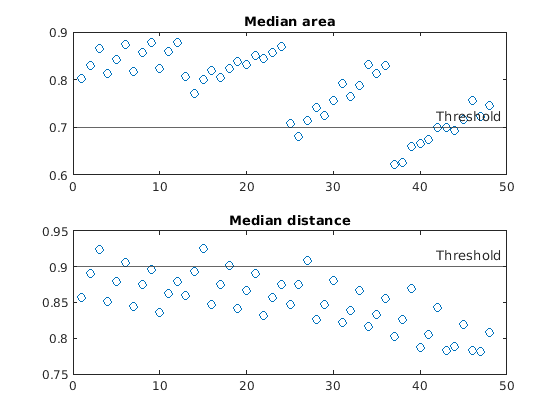

close all
MedianDistance = median(DistanceMetric');
MedianArea = median(AreaMetric');
TresArea = 0.7;
TresDist = 0.9;

subplot(2,1,1)
plot(MedianArea, 'o')
hold on
yline(TresArea,'-','Threshold');
title('Median area')

subplot(2,1,2)
plot(MedianDistance, 'o')
hold on
yline(TresDist,'-','Threshold');
title('Median distance')

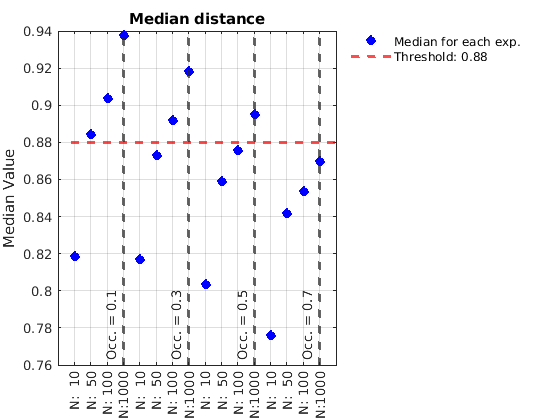

figure
plot(MedianDistance, 'o','linewidth',2,'MarkerFaceColor','b', 'color','b')
hold on

xlim([0 17])
yl = yline(TresDist,'r--',' ','linewidth',2);
yl.LabelHorizontalAlignment = 'left';
yl.LabelVerticalAlignment = 'middle';
ylabel('Median Value')
lgnd = legend({'Median for each exp.','Threshold: 0.88'},'AutoUpdate','off');
set(lgnd,'color','none','EdgeColor', 'none','Location','bestoutside');
for i=1:4
    xl = xline(i*4,'--',{'Occ. = '+ string(OccupExp(i*4))},'linewidth',2);
    xl.LabelVerticalAlignment = 'bottom';
    xl.LabelHorizontalAlignment = 'left';
end
title('Median distance')
grid on
ax = gca;
ax.XTick= 1:16;
xtickangle(90)
% A = num2str(OccupExp(:));
B = num2str(SampExp(:));
% O = repmat('O:',[16 1]);s
S = repmat('N:',[16 1]);
E = repmat(' ',[16 1]);
ax.XTickLabel = cellstr(num2str([S, B]));

## Best Parameter Combination

AreaPoints = find(MedianArea >= TresArea);
DistancePoints = find(MedianDistance >= TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 6

Kruskal-Wallis Test

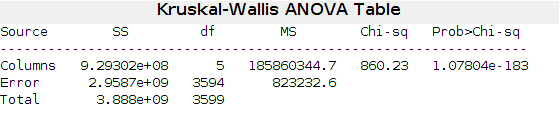

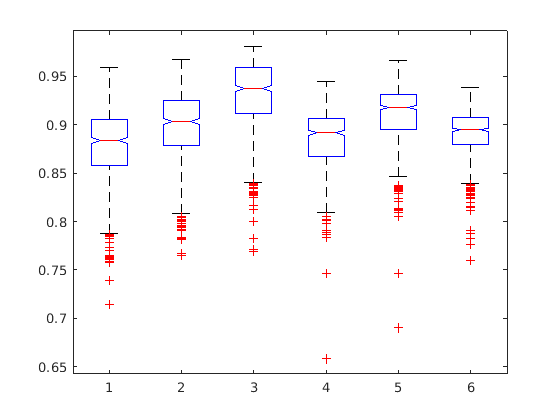

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

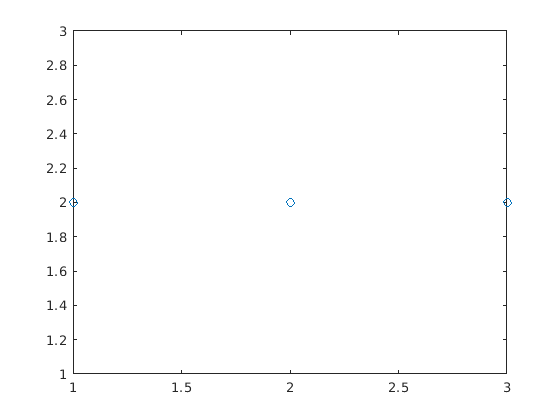

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 3
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:2


Samples:1000


Occupation:0.1


alpha:2


Samples:1000


Occupation:0.3


alpha:2


Samples:1000


Occupation:0.5


## Worst parameter combination

AreaPoints = find(MedianArea < TresArea);
DistancePoints = find(MedianDistance < TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 0

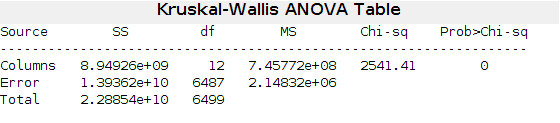

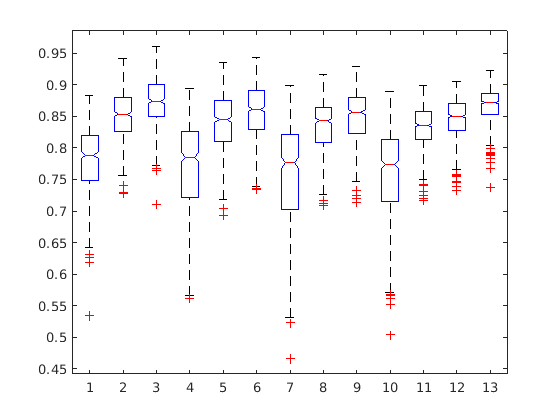

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

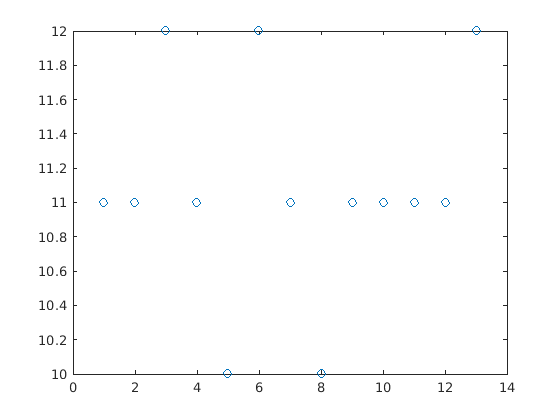

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 3
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:2


Samples:100


Occupation:0.1


alpha:2


Samples:100


Occupation:0.3


alpha:2


Samples:1000


Occupation:0.7


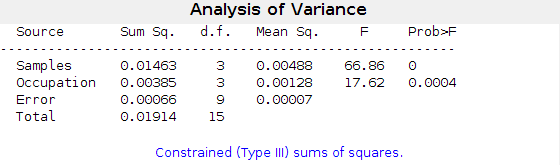

% [~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp},'model','interaction','varnames',{'Samples','Occupation'});
[~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp},'model','linear','varnames',{'Samples','Occupation'});

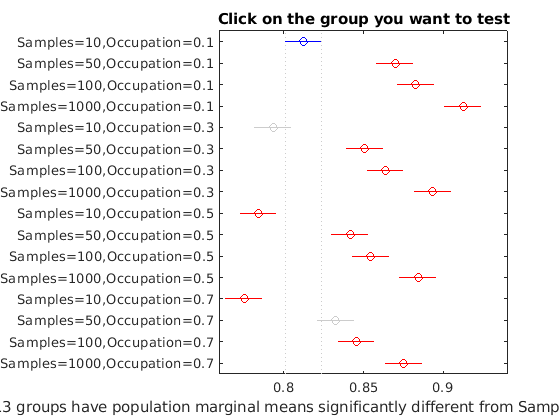

results = multcompare(stats,'Dimension',[1 2]);

Worst scenario

addpath Tool/VirtualSpeciesFunctions/
addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 10.981921 seconds.


min(min(DistanceMetric))

ans = 0.4897

[x,y] = find(DistanceMetric == min(min(DistanceMetric)))

x = 43

y = 1697

% x = 48;
disp("alpha:" + alpExp(x))

alpha:-1


disp("Samples:" + SampExp(x))

Samples:25


disp("Occupation:" + OccupExp(x))

Occupation:0.5


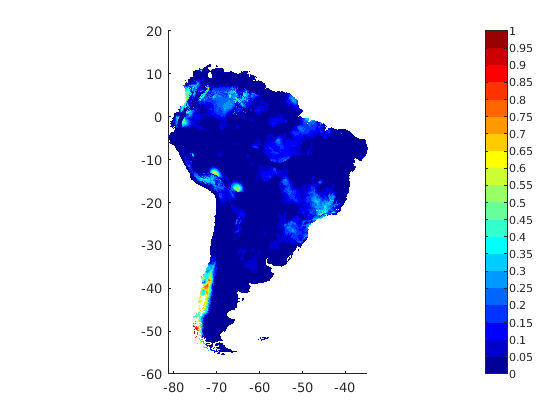

InfoInitialPoint = InitialPoint(Dimensions, Points(y, :)', Coeffs(y, :)'); 
MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, OccupExp(x), true);

----Modeling----
-Model 1


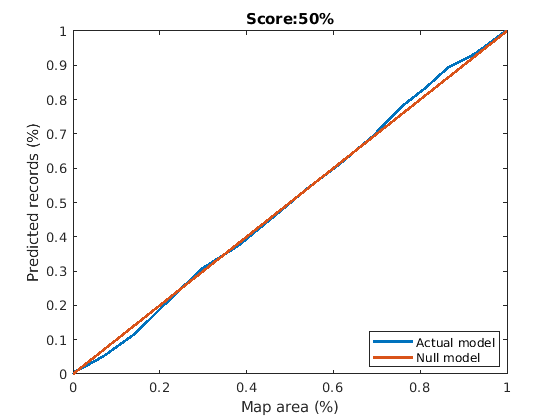

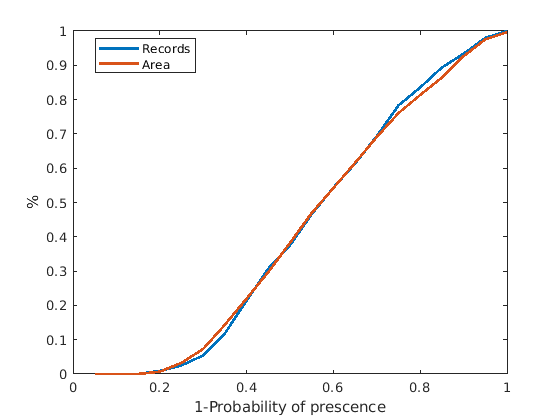

Elapsed time is 1.022127 seconds.


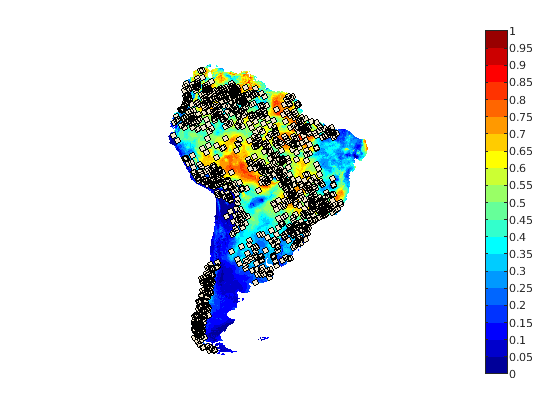

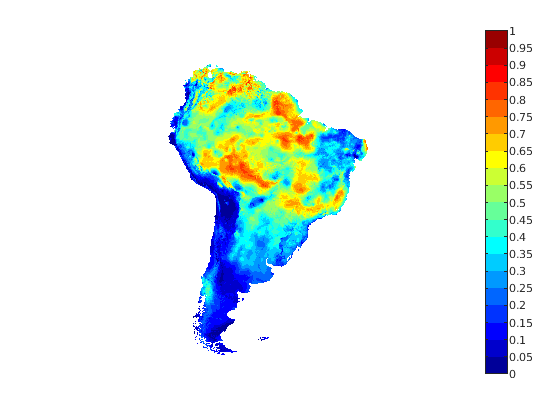

NicheMap = MapInfo.Map;
% T = samplingVS(Dimensions, MapInfo, SampExp(x), alpExp(x), true, 'GenSP', true, true);
T = readtable("example1.csv");
% data = bnm_prep(T, Dimensions, false, 0.7, true);
data = bnm_modeling(data, '', true);   

ModelMap = data.Map;
VectorMet = MapMetric(NicheMap, ModelMap, false)

VectorMet =     0.5382    0.6263


% writetable(T,"example1.csv")

Algorithm: GenSP_maxent.asc


    0.6356    0.6332



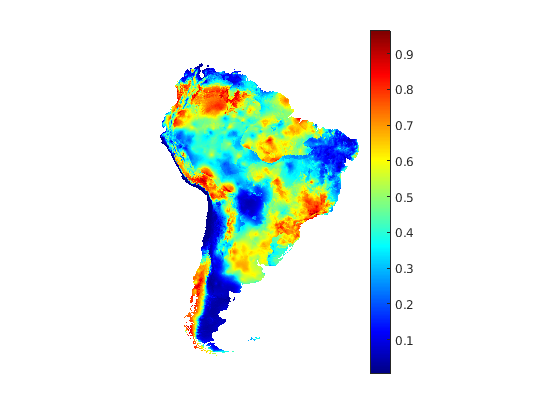

Algorithm: GenSP_maxlike.asc


    0.6076    0.3805



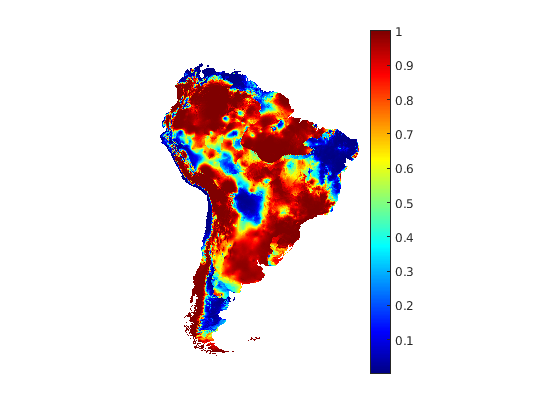

myDir ="/home/curie/MATLAB-Drive/VirtualSpecies";
myFiles = dir(fullfile(myDir,"*.asc"));
for k = 1:2
  baseFileName(k) = convertCharsToStrings(myFiles(k).name);
  fprintf(1, 'Algorithm: %s\n', baseFileName(k));
  [ModelMap, R] =  arcgridread(baseFileName(k));
  Table(k,:) = MapMetric(NicheMap, ModelMap, false);
  disp(Table(k,:));
  figure
  geoshow(ModelMap,R,'DisplayType','surface')  
  colormap jet
  colorbar
  axis off ; 
  drawnow
end

close all
[data,outland] = bnm_prep("example1.csv", Dimensions, false, 0.7, true, true);

----Modeling----
-Model 1


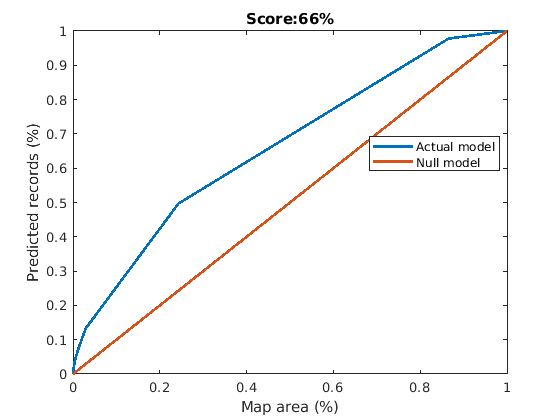

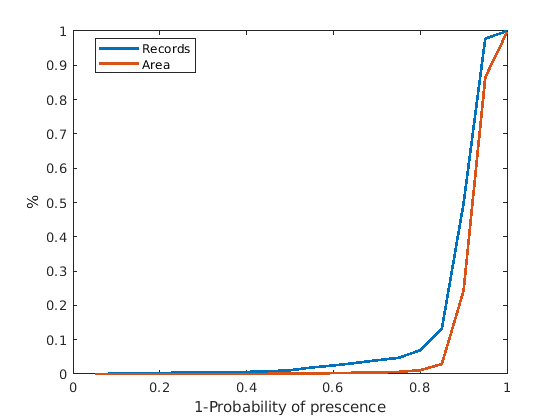

Elapsed time is 1.751543 seconds.


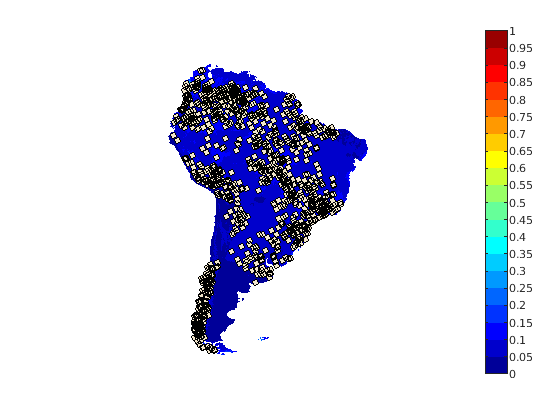

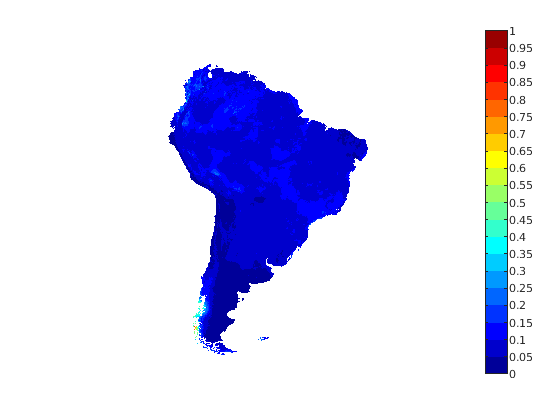

dataf = bnm_modeling(data, '', true, 4, false, outland);

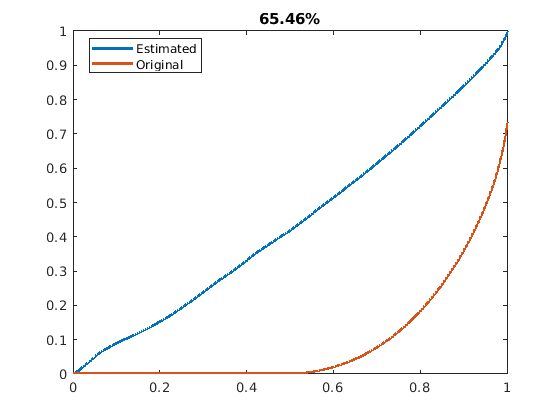

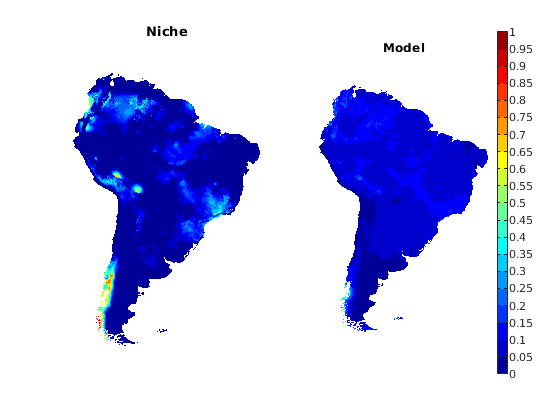

VectorMet =     0.6546    0.9282


VectorMet = MapMetric(NicheMap, dataf.Map, true, dataf.R)